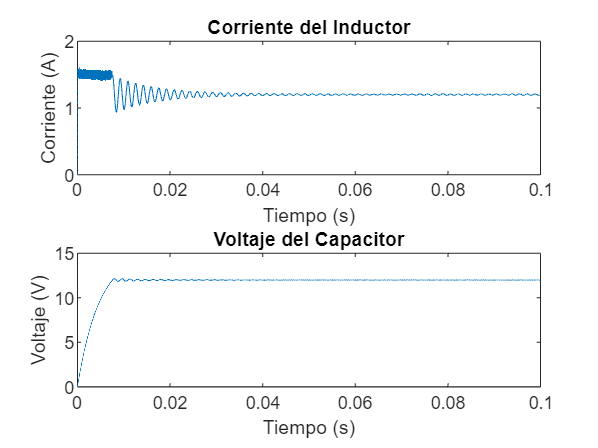

% Parámetros del Convertidor Buck
Vin = 12; % Voltaje de entrada
L = 150e-6; % Inductancia
C = 470e-6; % Capacitancia
R = 10; % Resistencia de carga
IL_ref = 1.5; % Corriente de referencia
h = 0.1; % Banda de histéresis
Rr = 1e-3; % Resistencia de recuperación inversa
Vr = 0.7; % Caída de voltaje de recuperación inversa

% Tiempo de simulación
tspan = [0 0.1];

% Condiciones iniciales
x0 = [0; 0]; % i_L(0) y v_C(0)

% Simulación del sistema
[t, x] = ode45(@(t, x) buckHysteresisThreeStates(t, x, Vin, L, C, R, IL_ref, h, Rr, Vr), tspan, x0);

% Graficar resultados
figure;
subplot(2,1,1);
plot(t, x(:,1));
title('Corriente del Inductor');
xlabel('Tiempo (s)');
ylabel('Corriente (A)');

subplot(2,1,2);
plot(t, x(:,2));
title('Voltaje del Capacitor');
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');

function dxdt = buckHysteresisThreeStates(t, x, Vin, L, C, R, IL_ref, h, Rr, Vr)
    iL = x(1);
    vC = x(2);
    
    % Control por histéresis
    persistent switchState;
    if isempty(switchState)
        switchState = 1; % Estado inicial del switch (encendido)
    end
    
    if iL >= IL_ref + h/2
        switchState = 0; % Apagar el switch
    elseif iL <= IL_ref - h/2
        switchState = 1; % Encender el switch
    end
    
    % Ecuaciones del convertidor Buck con tres estados
    if switchState
        % Estado 1: Interruptor cerrado
        diL_dt = (Vin - vC) / L;
    elseif iL > 0
        % Estado 2: Interruptor abierto
        diL_dt = -vC / L;
    else
        % Estado 3: Recuperación inversa del diodo
        diL_dt = (Vr - vC) / L;
    end
    dvC_dt = (iL - vC / R) / C;
    
    dxdt = [diL_dt; dvC_dt];
end